# EEGLAB Child Mind Example - ML

In this example, we use a large public EEG dataset from the [Child Mind Institute](https://childmind.org/), a non-profite organization for advancement of children mental health. The subset of dataset is used to train the existing convolutional neural network classification model **R-VGG_noNormalization**. Furthermore, we take advantage of the Array Datastore introduced in R2021a to facilitate handling of large files that might not fit in memory. 

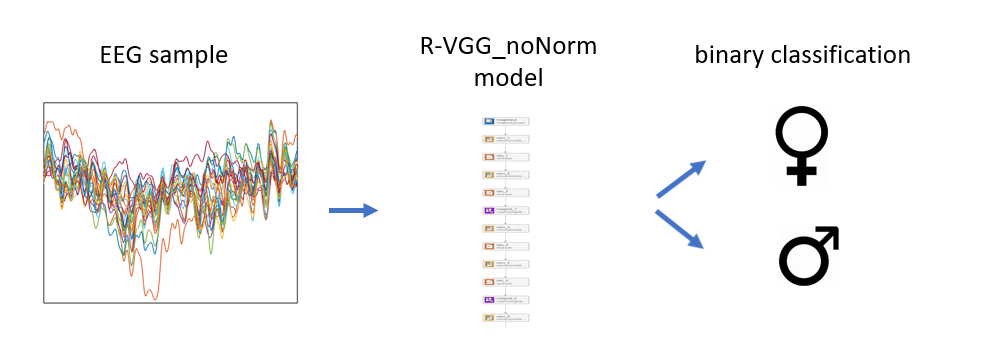

**Background on dataset**

The dataset is produced and shared as part of Healthy Brain Network (**HBN**) project led by the Child Mind Institute [1]. The HBN initiative efforts resulted in the creation and public sharing of a dataset from children and adolescents (**ages 5-21**), including up to **10,000 subjects**. The multi-modal brain recordings (EEG, MRI, fMRI) and a number of behavioral/physiological measures were collected during resting-state and performance on a variety of cognitive tasks. 

**Background on Example**

The subset of dataset used in this demonstration includes **EEG of 1,574 subjects** performing a resting-state task. EEG recordings were performed in a sound-shielded room, using a 128-channel EEG by Electrical Geodesics Inc. (EGI). During the recording, which lasted 5 minutes, subjects were instructed to open or close their eyes at various time points, while viewing a fixation cross located on the center of the screen. Individual subjects contributed ~80 sec of recordings during eyes closed periods. The data was preprocessed using [EEGLAB](https://sccn.ucsd.edu/eeglab/index.php), a versatile toolbox for EEG analysis [2]. Preprocessing included the mean baseline removal, down-sampling to 128 Hz, band-pass filtering (0.25-25 Hz) and re-referencing to the averaged mastoids. The example demonstrates the [**transfer learning**](https://en.wikipedia.org/wiki/Transfer_learning) capability of a model pretrained on image classification, showing a high performance in classification of biological sex based on multivariate EEG signal following just a few training cycles. More details on the entire preprocessing and model training pipeline could be found in the original publication by Truong et al. [3]. 

## Data Download/Local Loading 

Data is hosted at the [Swartz Center for Computational Neuroscience](https://sccn.ucsd.edu) server. If you are accessing data for the first time, the `data_download` helper function will save the data in your local directory of choice. The download should only take a few minutes. If the data is already stored locally, it will be loaded in workspace. The dataset has been split into **training** (~60%), **testing** (~10%) and **validation** (~30%) subsets.

% if downloading data from SCCN server, chose the local directory where it should be saved
% else, if data is already saved locally, chose the location

data_directory = uigetdir('C:\');

str_array1 = ["X","Y"];
str_array2 = ["test","train","val"];
server_path = 'https://sccn.ucsd.edu/eeglab/download/dl_child_mind_data';

[X_test, X_train, X_val, Y_test, Y_train, Y_val] = data_download(str_array1, str_array2, server_path, data_directory);

  Name            Size                Bytes  Class    Attributes

  X_test      15925x1             393029000  cell               

  Name             Size                 Bytes  Class    Attributes

  X_train      71138x1             1755685840  cell               

  Name           Size                Bytes  Class    Attributes

  X_val      39641x1             978339880  cell               

  Name            Size              Bytes  Class    Attributes

  Y_test      15925x4             2422241  table              

  Name             Size               Bytes  Class    Attributes

  Y_train      71138x4             10814617  table              

  Name           Size              Bytes  Class    Attributes

  Y_val      39641x4             6027073  table              



The built-in Matlab command [`whos`](https://www.mathworks.com/help/matlab/ref/whos.html) provides basic variable information (for context, check the `load_locally` helper function). The** X_*** files are **cell arrays**, each element containing individual **sample**. The **Y_*** files are **tables**, each column containing specific **labels** (subject ID, sex, handedness), with the *i*-th row of a table containing labels for the *i*-th sample in the corresponding X_* file (e.g. X_val and Y_val). 

## MATLAB Array-Type Datastastore

Matlab [datastore](https://www.mathworks.com/help/matlab/datastore.html) is a convenient way of storing the data too large to fit into a local machine memory. The arrayDatastore object by default has the attribute **OutputType: cell.** However, to ensure the data within the arrayDatastore is processed correctly within the network, the desired **OutputType** attribute instead needs to be type 'single' (for this particular dataset). To circumvent varying data-specifc output types, we can change output type to be same as original.

% creating arrayDatastore from local data load

train_data_ads = arrayDatastore(X_train, "OutputType", "same");
test_data_ads = arrayDatastore(X_test, "OutputType", "same");
val_data_ads = arrayDatastore(X_val, "OutputType", "same");


**Sample Visualization **

Samples used in this demonstration consist of 24 out of 128 electrodes from the original dataset, closely matching the montage used in a similar work [4], thereby facilitating the performance comparison. Duration of individual samples is 2 sec. 

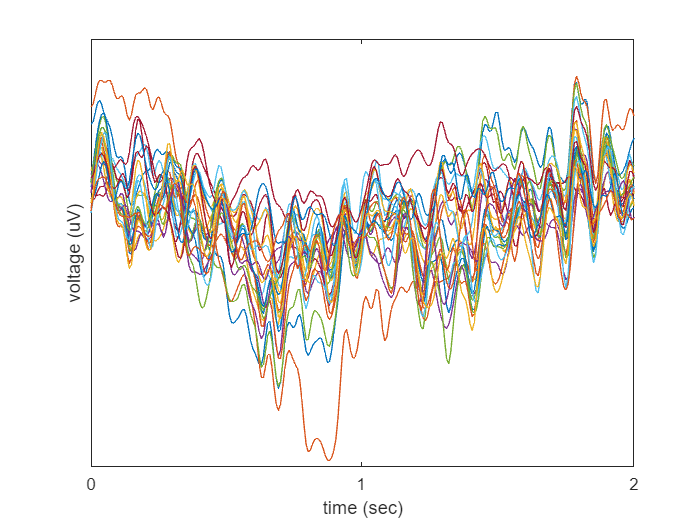

sample = preview(train_data_ads);
figure;plot(sample{1}');xlim([1 size(sample{1},2)]);yticks([]);xticks([]);
xticks([1 size(sample{1},2)/2 size(sample{1},2)]); xticklabels({'0','1','2'})
xlabel('time (sec)'); ylabel('voltage (uV)');

Individual lines represent the voltage samples from individual EEG channels, over 2 seconds of recording during eye-closed condition. 

## Label/Class Exploration

Labels are organized in separate tables for training, testing and validation (Y_train, Y_test and Y_val). Using Matlab [head](https://www.mathworks.com/help/matlab/ref/double.head.html) function is a convenient way to orientate on the table content and column indices of individual labels.

head(Y_test) % displays the first 8 entries

       Subject ID       Sex    EHQ1     EHQ2 
    ________________    ___    _____    _____

    {'NDARAA075AMK'}     1     6.728    65.57
    {'NDARAA075AMK'}     1     6.728    65.57
    {'NDARAA075AMK'}     1     6.728    65.57
    {'NDARAA075AMK'}     1     6.728    65.57
    {'NDARAA075AMK'}     1     6.728    65.57
    {'NDARAA075AMK'}     1     6.728    65.57
    {'NDARAA075AMK'}     1     6.728    65.57
    {'NDARAA075AMK'}     1     6.728    65.57



The label files contain 4 columns: 

- (1) - Subject_ID 

- (2) - Sex (1 = Female, 0 = Male), 

- (3-4) - EHQ_Total (+100 = Fully Right-Handed, -100 = Fully Left-Handed). Please check for a more detailed [explanation](https://lcbc-uio.github.io/questionnaires/articles/ehi.html#:~:text=The%20Edinburgh%20Handedness%20Inventory%20is%20a%20measurement%20scale,person%2C%20or%20by%20a%20person%20self-reporting%20hand%20use.) on the relation between the EHQ score and degree of handedness laterality.

### Selecting the Label for Classification

Choose a label that fits your desired model. In this case, we want to predict biological sex. This corresponds to our classifaction for Male/Female label column 2.

% select the label from drop-down menu
"Sex"

ans = "Sex"


selected_label=ans;
[lblds_test, lblds_train, lblds_val] = get_label_datastores(selected_label, Y_test, Y_train, Y_val);

`get_label_datastores` helper function extracts the selected label from the tables, converts them to categorical arrays (label format expected by the network) and puts them in array datastore.

#### **Checking the proportions of different classes**

Prior to model training, it's a good idea to compute the proportions of different class labels (in this case, Male/Female) in training, testing and validation datasets, to check if the datasets are balanced. **Balanced** datasets contain equal (or approximately equal) proportion of samples from each class. 

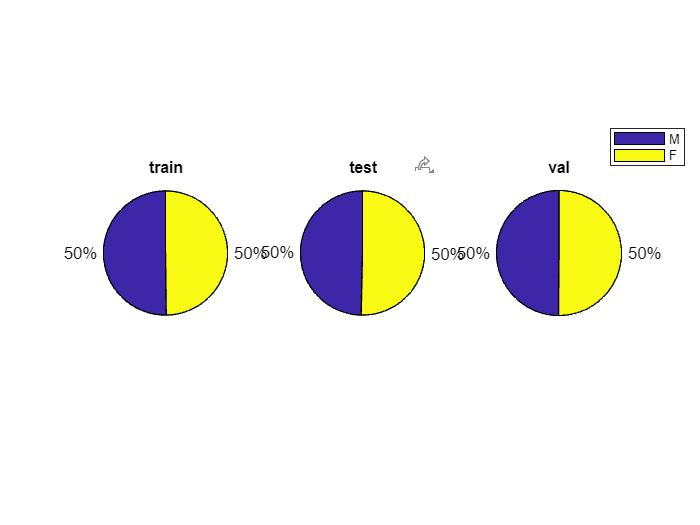

[class_proportions, class_labels_descr] = check_class_proportions(Y_train, Y_test, Y_val, selected_label);

figure;

for i = 1:3
    subplot(131);pie([class_proportions.train]);title('train');
    subplot(132);pie([class_proportions.test]);title('test');
    subplot(133);pie([class_proportions.val]);title('val'); 
end
legend(class_labels_descr);

subplot(1,3,3)
legend("Position", [0.87144,0.68294,0.10714,0.072619]);

The pie charts show that training, testing and validation datasets are balanced. For the balanced dataset with two classes, validation accuracy of 50% represents the **chance level **- a benchmark for estimating the training success. This is an important check, as the model trained on **imbalanced** datasets (e.g. 80% and 20%) could achieve 80% accuracy simply by classifying each sample as the overrepresented class, without learning the actual class representations.

## Combining Data and Label Datastores

We use the [combine](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.combine.html) function to put the data from the two datastores into a single CombinedDatastore, which is used as a consolidated input for VGG model.

% combine
ads_val = combine(val_data_ads, lblds_val');
ads_test = combine(test_data_ads, lblds_test');
ads_train = combine(train_data_ads, lblds_train');

% preview
preview(ads_val)

ans = 1×2 cell array
    {24×256 single}    {[0]}


Combined datastores are a final stage in data preparation, prior to network training. 

## Constructing & Training Network

Here we construct VGG, our existing model of choice [4]. This model represents a convolutional neural network with 27 layers, with the input layer (`imageInputLayer`) corresponding to the individual sample dimensions (24 x 256 in this case) and output layer (`classificationLayer`) reflecting the number of class labels (1 x 2). A detailed explanation on the concept of convolutional neural networks and overview of individual components (layers, activation functions etc.) could be found [here](https://en.wikipedia.org/wiki/Convolutional_neural_network).

convOpts = { 'Padding', 1, 'WeightL2Factor', 0 };
sample_size = size(X_train{1});
layers = [imageInputLayer(sample_size, 'Normalization', 'none') ...
        convolution2dLayer(3, 16, convOpts{:}) ...
        reluLayer() ...
        convolution2dLayer(3, 16, convOpts{:}) ...
        reluLayer() ...
        maxPooling2dLayer(2, 'Stride', 2) ...
        convolution2dLayer(3, 32, convOpts{:}) ...
        reluLayer() ...
        convolution2dLayer(3, 32, convOpts{:}) ...
        reluLayer() ...
        maxPooling2dLayer(2, 'Stride', 2) ...
        convolution2dLayer(3, 64, convOpts{:}) ...
        reluLayer() ...
        convolution2dLayer(3, 64, convOpts{:}) ...
        reluLayer() ...    
        convolution2dLayer(3, 64, convOpts{:}) ...
        reluLayer() ...    
        maxPooling2dLayer(2, 'Stride', 2) ...
        fullyConnectedLayer(1024) ...
        reluLayer() ...    
        dropoutLayer(0.5) ...
        fullyConnectedLayer(1024) ...
        reluLayer() ...    
        dropoutLayer(0.5) ...
        fullyConnectedLayer(2) ...
        softmaxLayer() ...
        classificationLayer ];
disp(layers)

  1×27 Layer array with layers:

     1   ''   Image Input             24×256×1 images
     2   ''   2-D Convolution         16 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   ''   ReLU                    ReLU
     4   ''   2-D Convolution         16 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     5   ''   ReLU                    ReLU
     6   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     8   ''   ReLU                    ReLU
     9   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
    10   ''   ReLU                    ReLU
    11   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    12   ''   2-D Convolution         64 3×3 convolutions wi

Convolutional neural networks are powerfull tool for image classification. In this example, they are tested on classifying the multi-variate EEG data, with binary output.

**Defining the Training Options**

`trainingOptions` function takes as input arguments a number of adjustable training options, providing the interface for tuning the training process, depending on the performance.

% Training
miniBatchSize = 40; % the n of samples presented to network in a single training iteration.
% The product of mini-batch size and n of training iterations should be as close as possible to the number of training samples.
valFreq = floor(numel(X_train)/miniBatchSize);
options = trainingOptions('adam', ...
            'InitialLearnRate',0.0005, ...
            'SquaredGradientDecayFactor',0.99, ...
            'MaxEpochs',30, ... % the n of training epochs. All the samples are presented once during a single epoch.
            'MiniBatchSize',miniBatchSize, ...
            'Plots','training-progress',...% allows the real-time monitoring of training progress
            'ValidationData',ads_val, ...% the datastore containing validation labels
            'ValidationFrequency', valFreq); % the n of training iterations between the period testing of validation accuracy 
            % Ideally, following each training epoch
array_net = trainNetwork(ads_train,layers,options);

Training on single CPU.


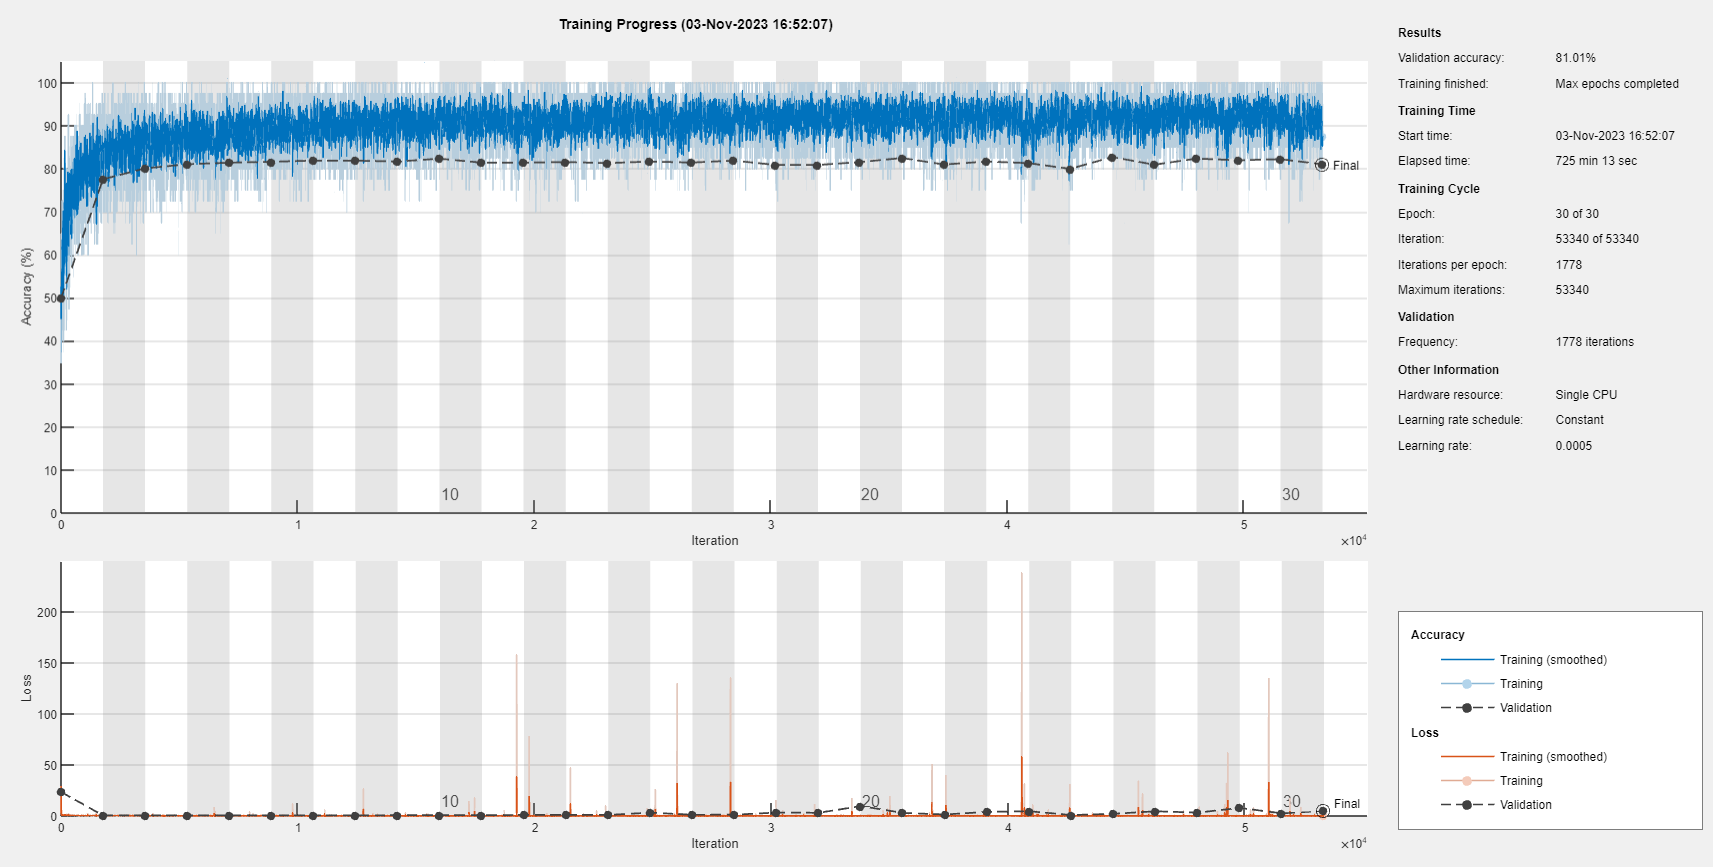

`array_net `represents the trained network that could be used for inference (in this example, sex classification based on EEG samples). We can see that the accuracy on validation set increases to ~80% already after the first training epoch and asymptotes around this level.

## Testing Trained Network

Finally, classification accuracy is tested against the testing data and expressed as the percentage of correct classifications.

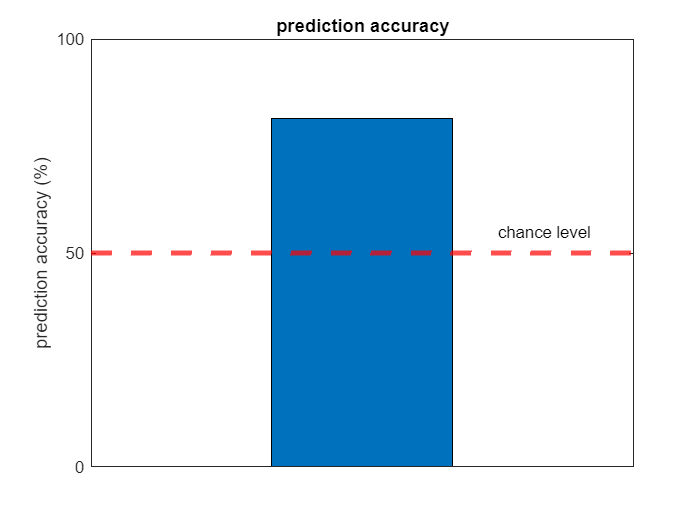

y_pred = classify(array_net, ads_test);

% Accuracy 
labels = Y_test.Properties.VariableNames;
column_ind = find(strcmp(selected_label,labels)==1);

lblcat_test = categorical(table2array(Y_test(:,column_ind)));
acc = mean(y_pred == lblcat_test);

figure;bar(acc*100);
title('prediction accuracy')
yline(50,'r--','LineWidth',3);
ylabel('prediction accuracy (%)');
xticks([]);yticks([0 50 100]);yticklabels({'0','50','100'});ylim([0 100])
txt = 'chance level';
text(1.6,55,txt)

Prediction accuracy is above 80%, with the chance level being 50% (based on the balanced distribution of classes in the dataset). This result reflects the model's capacity to learn the subject's biological sex representation from the EEG data in the population of 5-21 years olds.

## Confusion Matrix

Next, we can check if the probability of misclassification differs between the classes. For example, are the samples from male subjects more likely to be missclassified as samples from female subjects (**M→F**) or the other way around (**F→M**)? Or alternatively, the misclassification probability might not be class-dependent.

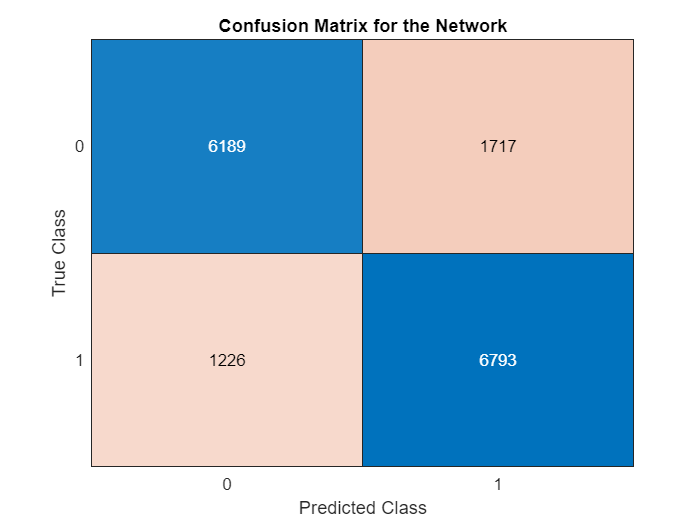

C = confusionmat(y_pred, lblcat_test);

figure;
cm = confusionchart(lblcat_test, y_pred);
cm.Title = ['Confusion Matrix for the Network'];

**Misclassification Errors**

From the confusion matrix, it appears as the probability of male samples being misclassified as female (**M→F**, top right quadrant of the confusion matrix) is higher than the probability of female samples being misclassified as male (**F→M**, bottom left quadrant of the confusion matrix). We can show this graphically as a pie chart.

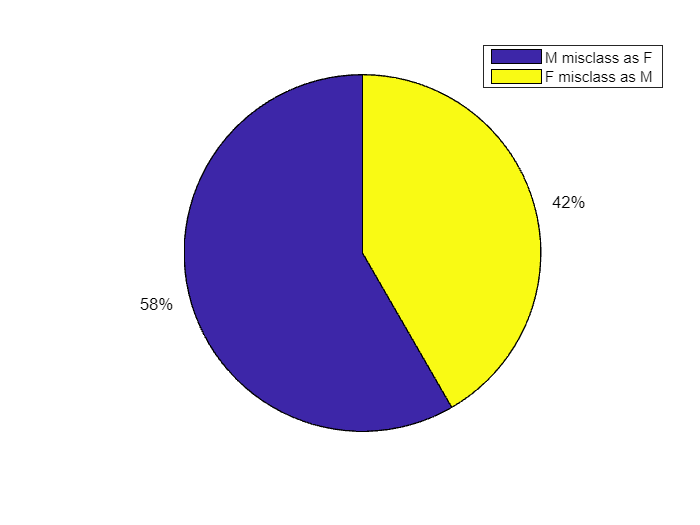

M_miscl_asF = cm.NormalizedValues(1,2);
F_miscl_asM = cm.NormalizedValues(2,1);

figure;pie([M_miscl_asF,F_miscl_asM])
legend('M misclass as F','F misclass as M')

legend("Position", [0.68935,0.83198,0.25714,0.082143])

The chart above shows that the probability of **M→F** misclassification is almost 50% higher than the **F→M** misclassification, despite the equal representation of both classes in the dataset.

## **References**

- L. Alexander, J. Escalera, L. Ai et al., "An open resource for transdiagnostic research in pediatric mental health and learning disorders", *Scientific Data*, vol. 4, pp. 170181, 2017.

-  A. Delorme and S. Makeig, "EEGLAB: an open source toolbox for analysis of single-trial EEG dynamics including independent component analysis", *Journal of neuroscience methods*, vol. 134, no. 1, pp. 9-21, 2004.

- D. Truong, M. Sinha, K.U. Venkataraju, M. Milham and A. Delorme. A streamable large-scale clinical EEG dataset for Deep Learning. In *2022 44th Annual International Conference of the IEEE Engineering in Medicine & Biology Society (EMBC)* (pp. 1058-1061). IEEE, 2022.

- M. J. A. M. Van Putten, S. Olbrich and M. Arns, "Predicting sex from brain rhythms with deep learning", *Scientific Reports*, vol. 8, 2018.

**Helper Functions**

function [X_test, X_train, X_val, Y_test, Y_train, Y_val] = data_download(str_array1, str_array2, server_path, data_directory)

%checking if the data exists in the local directory and downloading from SCSN server otherwise

for i = 1:numel(str_array1)
    for ii = 1:numel(str_array2)
        if exist(sprintf('%s/%s_%s.mat',data_directory,str_array1(i),str_array2(ii)))==0
            FileFullPath = websave(sprintf('%s/%s_%s.mat',data_directory,str_array1(i),str_array2(ii)), sprintf('%s/%s/%s_%s.mat',server_path,str_array2(ii),str_array1(i),str_array2(ii)));
        end
    end
end

%loading from local storage

[X_test, X_train, X_val, Y_test, Y_train, Y_val] = load_locally(str_array1, str_array2,data_directory);

end



function [X_test, X_train, X_val, Y_test, Y_train, Y_val] = load_locally(str_array1, str_array2,data_directory)

for i = 1:numel(str_array1)
    for ii = 1:numel(str_array2)
    load(sprintf('%s/%s_%s.mat',data_directory,str_array1(i),str_array2(ii)));
    end
end

temp = cell(size(X_test,3), 1);
for i = 1:size(X_test,3)
    temp{i} = X_test(:,:,i);
end
X_test = temp; clear temp;
whos X_test;

temp = cell(size(X_train,3), 1);
for i = 1:size(X_train,3)
    temp{i} = X_train(:,:,i);
end
X_train = temp; clear temp;
whos X_train;

temp = cell(size(X_val,3), 1);
for i = 1:size(X_val,3)
    temp{i} = X_val(:,:,i);
end
X_val = temp; clear temp;
whos X_val;

classes = {'Subject ID','Sex','EHQ1','EHQ2'};

Y_test = cell2table(Y_test);
Y_test.Properties.VariableNames = classes;
whos Y_test

Y_train = cell2table(Y_train);
Y_train.Properties.VariableNames = classes;
whos Y_train

Y_val = cell2table(Y_val);
Y_val.Properties.VariableNames = classes;
whos Y_val

end



function [lblds_test, lblds_train, lblds_val] = get_label_datastores(selected_label, Y_test, Y_train, Y_val)

labels = Y_train.Properties.VariableNames;

column_ind = find(strcmp(selected_label,labels)==1);

lblds_test = arrayDatastore(categorical(table2array(Y_test(:,column_ind))));
lblds_train = arrayDatastore(categorical(table2array(Y_train(:,column_ind))));
lblds_val = arrayDatastore(categorical(table2array(Y_val(:,column_ind))));

end

function [class_proportions, class_labels_descr] = check_class_proportions(Y_train, Y_test, Y_val, selected_label)

labels = Y_test.Properties.VariableNames;
column_ind = find(strcmp(selected_label,labels)==1);

labels_cat_test = categorical(table2array(Y_test(:,column_ind)));
labels_cat_train = categorical(table2array(Y_train(:,column_ind)));
labels_cat_val = categorical(table2array(Y_val(:,column_ind)));

classes = unique(labels_cat_test);

for i = 1:numel(classes)
    class_proportions.train(i)=numel(find(labels_cat_train==classes(i)))/numel(labels_cat_train);
    class_proportions.test(i)=numel(find(labels_cat_test==classes(i)))/numel(labels_cat_test);
    class_proportions.val(i)=numel(find(labels_cat_val==classes(i)))/numel(labels_cat_val);
end

if strcmp(selected_label,'Sex')==1
    class_labels_descr = {'M','F'};
elseif strcmp(selected_label,'Handedness')==1
    class_labels_descr = {'L','R'};
end

end
